**Gruppo 2 (esercizio 2)**

Considerare vettori con un numero n di componenti da 2 a 20, le cui componenti sono punti equidistanti nell'intervallo [-1,1], oppure un intervallo [a, b] con a, b numeri reali. Calcolare le tre norme vettoriali al crescere di n e farne il confronto analizzando il grafico dei risultati.

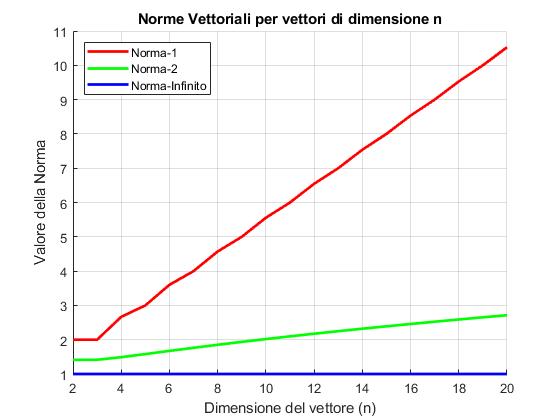

g2e2(-1,1, 2, 20)

**Gruppo 3** (esercizio 2)

               Norm1               Norm2                Inf              Frobenius    
          ________________    ________________    ________________    ________________

    2                  1.5      1.267591879244                 1.5    1.26929551764398
    3     1.83333333333333    1.40831892712365    1.83333333333333    1.41362418390934
    4     2.08333333333333    1.50021428005924    2.08333333333333    1.50973409981831
    5     2.28333333333333    1.56705069109823    2.28333333333333    1.58090626327202
    6                 2.45    1.61889985892434                2.45    1.63702239330239
    7     2.59285714285714    1.66088533892693    2.59285714285714    1.68313248884359
    8     2.71785714285714    1.69593899692195  

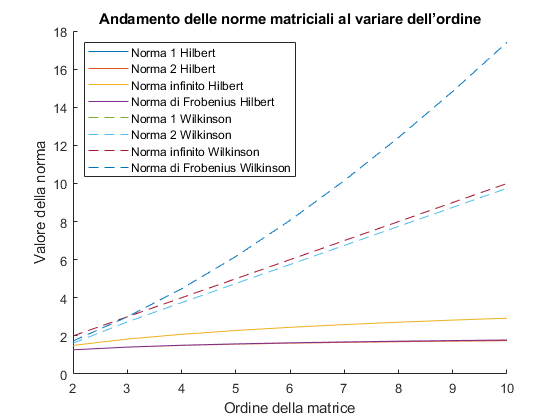

g3e2(2,10)

**Gruppo 4 (esercizio 1)**

Studiare, analizzando i risultati, l'indice di condizionamento di alcune famiglie di matrici al crescere dell'ordine n da 2 a 10 rispetto a 2 delle norme studiate.

Fare il grafico dell'andamento dell'indice di condizionamento, confrontare, analizzare e commentare i risultati.

Usare la scala logaritmica sull'asse delle ordinate per avere un grafico migliore

                 Norm2                  NormInf       
          ____________________    ____________________

    2          19.281470067904                      27
    3         524.056777586063        748.000000000004
    4          15513.738738929        28374.9999999973
    5            476607.250241        943655.999999332
    6         14951058.6414534        29070279.0011847
    7         475367356.911439        985194886.884583
    8          15257575566.628        33872788559.0714
    9         493153404551.012        1099649476469.95
    10        16025028168113.2        35352333500163.5
    11         522020733204515    1.22947675949517e+15
    12     1.6211639047475e+16    3.84196105244298e+16
    13    4.

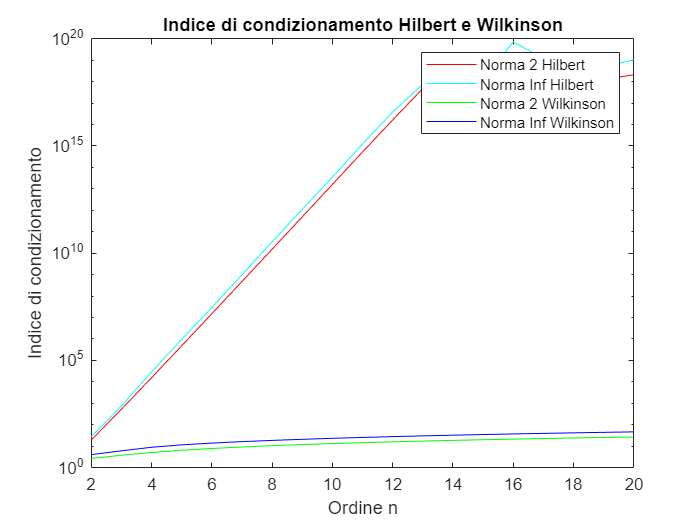

g4e1(2,20)

**Gruppo 5 (esercizio 2)**

Calcolare il determinante della matrice di una matrice A con ordine n > 10.

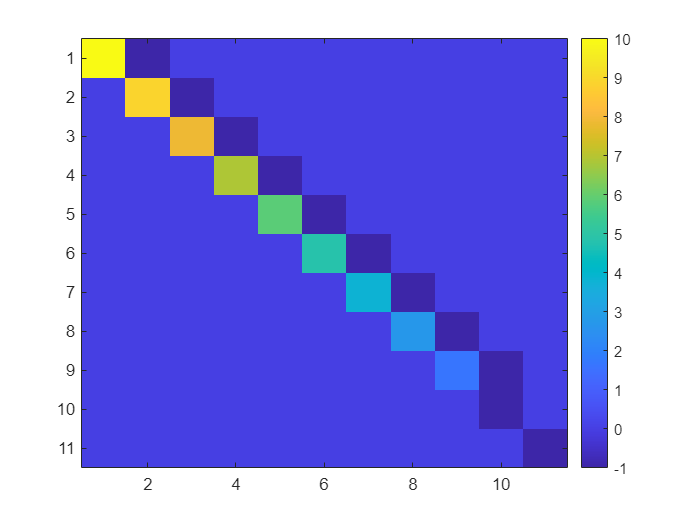

A = wilki(11);
[A1, detA1] = det_gauss_pp(A);
imagesc(A1); colorbar

disp(detA1);

    -2314230



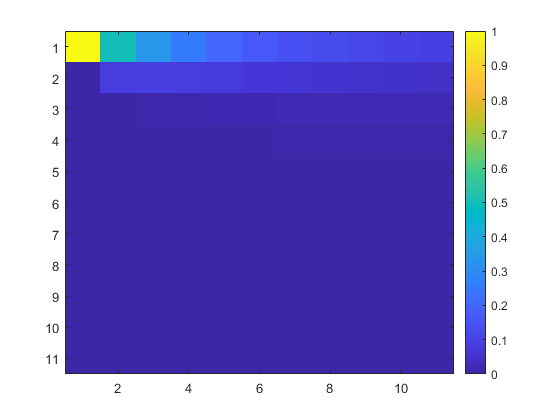

B = hilb(11);
[B1, detB1] = det_gauss_pp(B);
imagesc(B1); colorbar

disp(detB1)

     3.026666989881672e-65



**Guppo 6 **(esercizio 2)

Metodo di Jacobi:
Soluzione:    1.000000000000000
   1.000000000000000
   1.000000000000000

Iterazioni: 84
Metodo di Gauss-Seidel:
Soluzione:    1.000000000000000
   1.000000000000000
   1.000000000000000

Iterazioni: 145


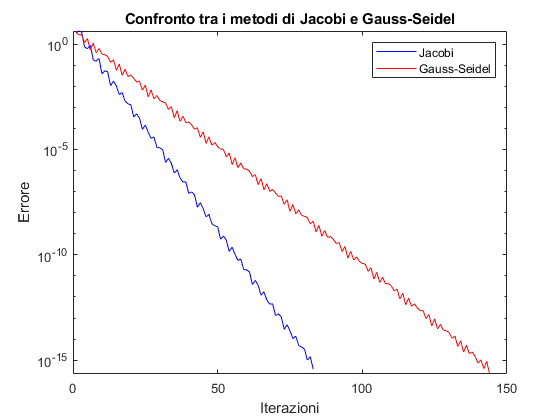

A=[7,6,9;4,5,-4;-7,-3,8];
b=[22,5,-2];
g6e2(A, b, 1000, 1e-16)

Metodo di Jacobi:
Soluzione:      1
     1
     1
     1

Iterazioni: 30
Metodo di Gauss-Seidel:
Soluzione:      1
     1
     1
     1

Iterazioni: 28


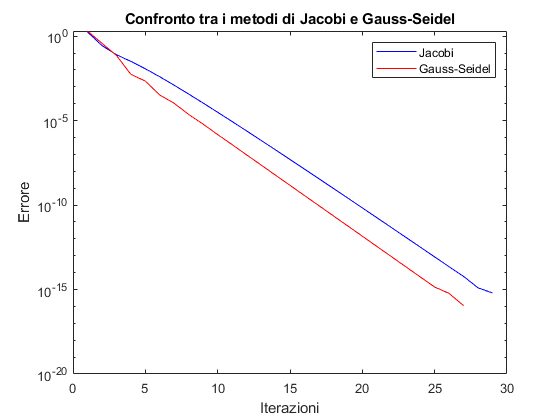

A=[-4,-1,1,1;0,-4,-1,1;-1,-1,4,1;1,-1,0,4];
b=[-3,-4, 3, 4];
g6e2(A, b, 1000, 1e-16)

Metodo di Jacobi:
Soluzione:      1
     1
     1

Iterazioni: 47
Metodo di Gauss-Seidel:
Soluzione:      1
     1
     1

Iterazioni: 11


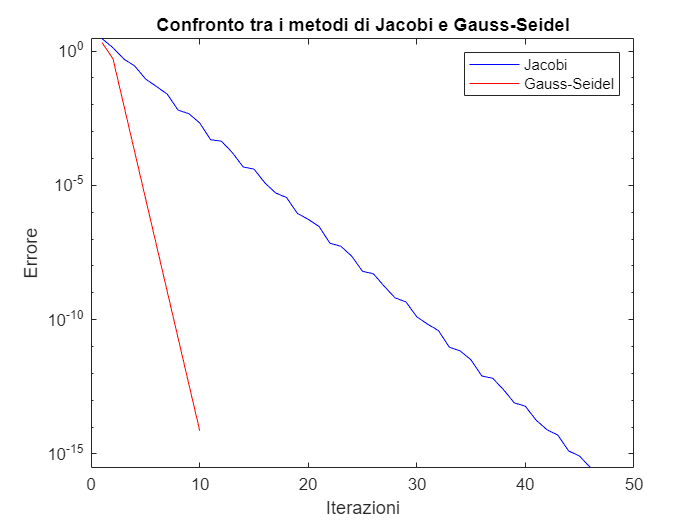

A=[4,1,1;2,-9,0;0,-8,-6];
b=[6, -7, -14];
g6e2(A, b, 1000, 1e-16)

**Gruppo 7 **(esercizio 2)

% Matrice a Freccia
n = 15;  % per n > 12
A = 19 * eye(n);  % matrice diagonale a 19
A(1, 2:n) = -1;  % prima riga restante a -1
A(2:n, 1) = 1;  % prima colonna restante a 1

**Matrice Freeccia:**

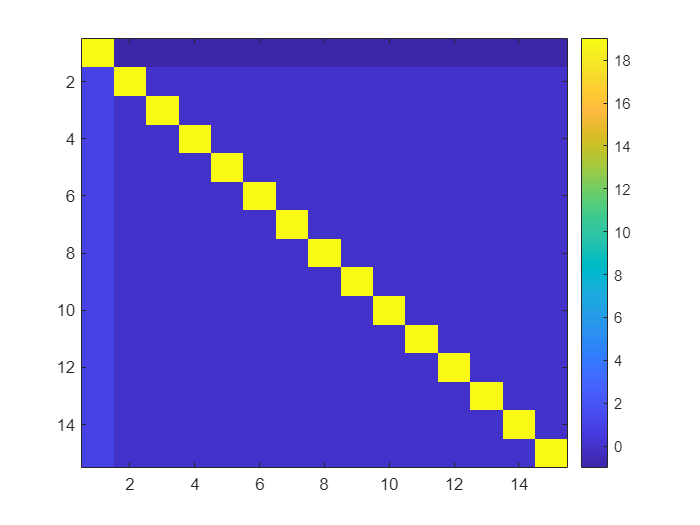

imagesc(A); colorbar

b = zeros(n,1) + 20;
b(1)=5;
[iter,e]=jacobi(A,b,ones(n,1),1000,1e-6)

iter =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


e =      1


**Gruppo 7  (esercizio 3)**

Considerare il sistema lineare con matrice A=[0.96326,0.81321;0.81321,0.68654] e vettore dei termini noti b=[0.88824;0.74988].

Risovi i punti A,B,C,D.

% Definizione della matrice A e del vettore b
A = [0.96326, 0.81321; 0.81321, 0.68654];
b = [0.88824; 0.74988];

% Verifica se A è definita positiva
isPositive = issymmetric(A) && all(eig(A) > 0);
if isPositive
    % Metodo di Cholesky
    x_cholesky = cholesky(A,b);
    % Calcolo della norma del residuo per Cholesky (norma 2)
    residuo_cholesky = norma(A*x_cholesky - b,2); 

    % Stampa dei risultati del metodo di Cholesky
    fprintf('Soluzione Cholesky: [%f; %f]\n', x_cholesky);
    fprintf('Norma del Residuo Cholesky: %f\n\n', residuo_cholesky);
else
    disp('La matrice A non è definita positiva')
    return
end

Soluzione Cholesky: [0.394728; 0.624703]


Norma del Residuo Cholesky: 0.000000



% Calcolo della matrice di iterazione per Gauss-Seidel
D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);
M_GS = (D + L)^-1 * U; 

% Calcolo della norma della matrice di iterazione (norma 2)
norm_M_GS = norm(M_GS); 

% Calcolo del raggio spettrale della matrice di iterazione
raggio_spettrale_M_GS = max(abs(eig(M_GS)));

% Definizione dei vettori iniziali
x0_vec = [[0.33116; 0.7], [0; 0], [1; 1]];

% Iterazione per ogni vettore iniziale
n = size(x0_vec, 2);
for i = 1 : n
    x0 = x0_vec(:, i);
    [x_gauss_seidel, iter, error] = gauss_seidel(A, b, x0, 1000, 1e-6);

    % Stampa dei risultati
    fprintf('Vettore iniziale: [%f; %f]\n', x0);
    fprintf('Soluzione Gauss-Seidel: [%f; %f]\n', x_gauss_seidel);
    fprintf('Iterazioni Gauss-Seidel: %d\n', iter);
    fprintf('Norma del Residuo Gauss-Seidel: %f\n\n', norm(A*x_gauss_seidel - b));
    fprintf('------------------------------------------');
end

Vettore iniziale: [0.331160; 0.700000]


Soluzione Gauss-Seidel: [0.331160; 0.699999]


Iterazioni Gauss-Seidel: 1


Norma del Residuo Gauss-Seidel: 0.000001



------------------------------------------

Vettore iniziale: [0.000000; 0.000000]


Soluzione Gauss-Seidel: [0.917347; 0.005657]


Iterazioni Gauss-Seidel: 1000


Norma del Residuo Gauss-Seidel: 0.000005



------------------------------------------

Vettore iniziale: [1.000000; 1.000000]


Soluzione Gauss-Seidel: [0.080758; 0.996601]


Iterazioni Gauss-Seidel: 1000


Norma del Residuo Gauss-Seidel: 0.000003



------------------------------------------

% Calcolo dell'indice di condizionamento di A
cond_A = cond(A); % ||A|| * ||inv(A)||
% Stampa dei risultati
fprintf('Indice di condizionamento di A: %f\n', cond_A);

Indice di condizionamento di A: 452408.956885


fprintf('Norma della matrice di iterazione: %f\n', norm_M_GS);

Norma della matrice di iterazione: 1.308702


fprintf('Raggio spettrale della matrice di iterazione: %f\n', raggio_spettrale_M_GS);

Raggio spettrale della matrice di iterazione: 0.999991


**Gruppo 8 (esercizio 1)**

Verificare la bontà del metodo di interpolazione di Lagrange (o di Newton) su alcune

funzioni, di cui si conosce la formula analitica, considerando tabulati con 5, 6, 11, 12, 20, 25

punti equidistanti. Analizzare il grafico degli errori. Costruire la tabella contenente la norma

dell'errore.

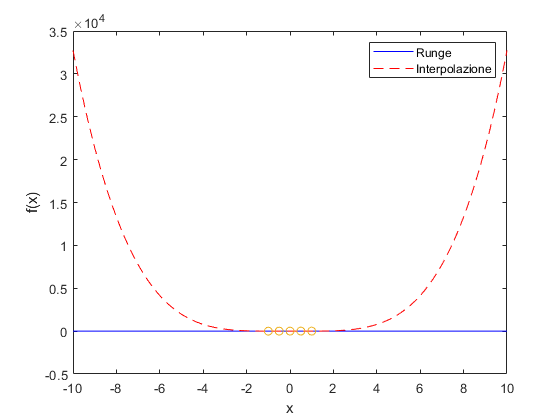

y1 = @(x) 1./(1 + 25*x.^2); % Runge
y2 = @(x) x./(1 + x.^2);

% Punti per la visualizzazione del polinomio interpolante
x = linspace(-10, 10, 101);
% Tabella di 5 punti 
table = funTable(y1, -1, 1, 5, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

     x              f(x)                    yi                 Errore      
    ____    ____________________    __________________    _________________

     -10     0.00039984006397441      32729.7798408488     32729.7794410087
    -9.8     0.00041631973355537      30172.7175066313     30172.7170903116
    -9.6    0.000433839479392625      27768.1724137931     27768.1719799536
    -9.4    0.000452488687782805      25509.9694960212     25509.9690435325
    -9.2    0.000472366556447803      23392.0610079576      23392.060535591
      -9    0.000493583415597236      21408.5265251989     21408.5260316155
    -8.8    0.000516262261228704      19553.5729442971     19553.5724280348
    -8.6    0.000540540540540541      17821.5344827586     17821.5339422181
    -8.4     0.00056657223796034      16206.8726790451     16206.8721124729
    -8.2    0.0005945303210

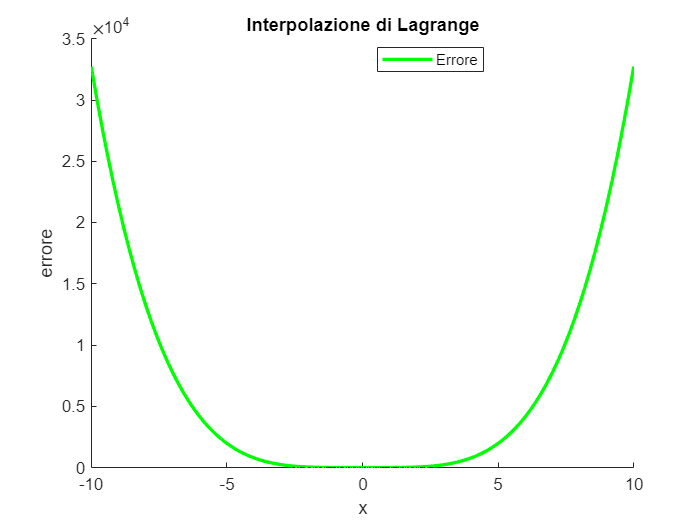


Errore Norma: 113643.2396


errLagrange(x, yi, y1);

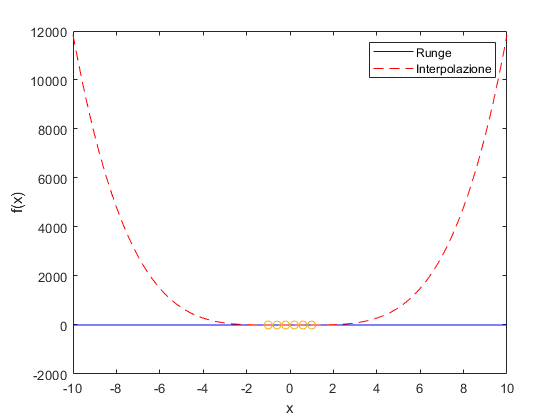

% Tabella di 6 punti 
table = funTable(y1, -1, 1, 6, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

     x              f(x)                    yi                  Errore      
    ____    ____________________    ___________________    _________________

     -10     0.00039984006397441       11846.7211538461      11846.720754006
    -9.8     0.00041631973355537       10920.5000000001     10920.4995836803
    -9.6    0.000433839479392625       10049.5519230769     10049.5514892374
    -9.4    0.000452488687782805        9231.6384615384     9231.63800904971
    -9.2    0.000472366556447803        8464.5673076923     8464.56683532574
      -9    0.000493583415597236       7746.19230769229     7746.19181410887
    -8.8    0.000516262261228704        7074.4134615385     7074.41294527624
    -8.6    0.000540540540540541       6447.17692307688     6447.17638253634
    -8.4     0.00056657223796034       5862.47499999997     5862.47443342773
    -8.2    0.00

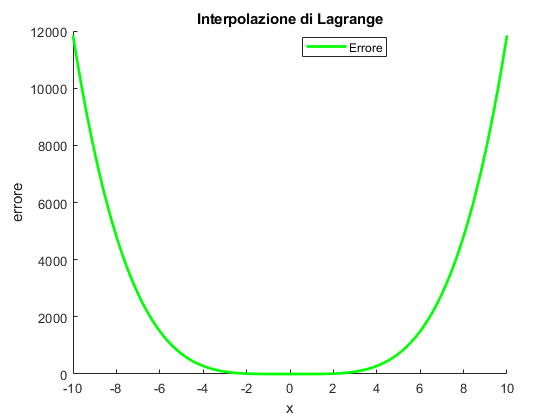


Errore Norma: 41117.8186


errLagrange(x, yi, y1);

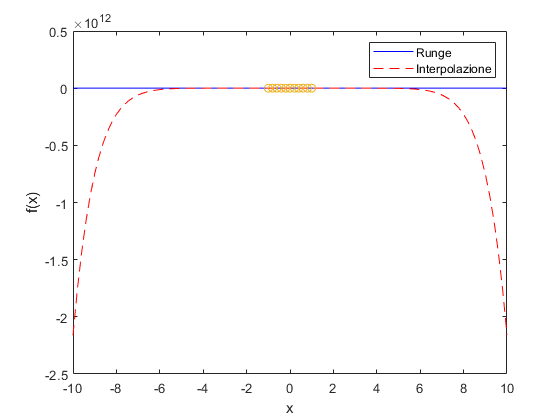

% Tabella di 11 punti 
table = funTable(y1, -1, 1, 11, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

     x              f(x)                    yi                 Errore     
    ____    ____________________    __________________    ________________

     -10     0.00039984006397441        -2160306672499       2160306672499
    -9.8     0.00041631973355537      -1763486577239.5     1763486577239.5
    -9.6    0.000433839479392625      -1433488076235.8     1433488076235.8
    -9.4    0.000452488687782805      -1160119648225.3     1160119648225.3
    -9.2    0.000472366556447803     -934576130448.539     934576130448.54
      -9    0.000493583415597236      -749273890128.92    749273890128.921
    -8.8    0.000516262261228704     -597702654690.403    597702654690.404
    -8.6    0.000540540540540541     -474292626196.935    474292626196.936
    -8.4     0.00056657223796034     -374295592335.235    374295592335.235
    -8.2    0.000594530321046373     -

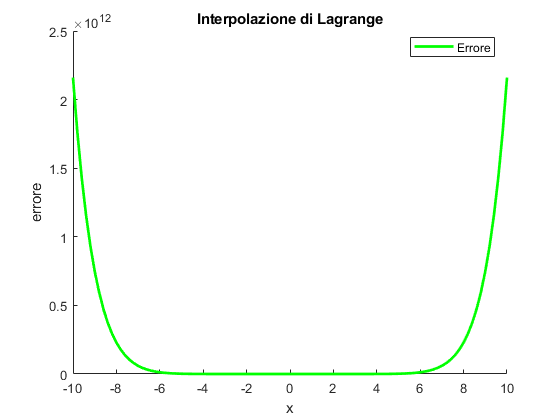


Errore Norma: 5205489741802.7812


errLagrange(x, yi, y1);

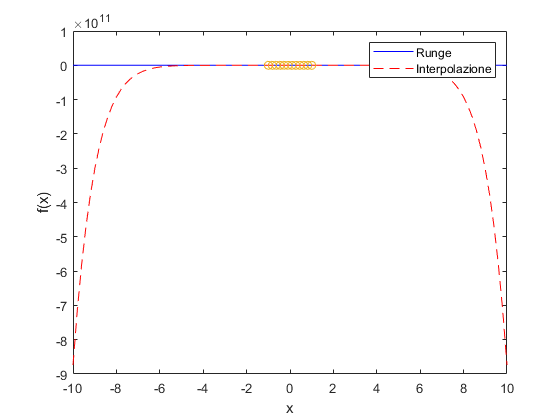


% Tabella di 12 punti 
table = funTable(y1, -1, 1, 12, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

     x              f(x)                    yi                   Errore      
    ____    ____________________    ___________________    __________________

     -10     0.00039984006397441      -873646831770.604      873646831770.605
    -9.8     0.00041631973355537      -713120928166.286      713120928166.286
    -9.6    0.000433839479392625       -579633881822.83       579633881822.83
    -9.4    0.000452488687782805      -469060741434.818      469060741434.819
    -9.2    0.000472366556447803      -377837798925.767      377837798925.768
      -9    0.000493583415597236      -302895848828.166      302895848828.167
    -8.8    0.000516262261228704      -241600193999.058      241600193999.059
    -8.6    0.000540540540540541      -191696840961.384      191696840961.384
    -8.4     0.00056657223796034      -151264363336.796      151264363336.797
    -

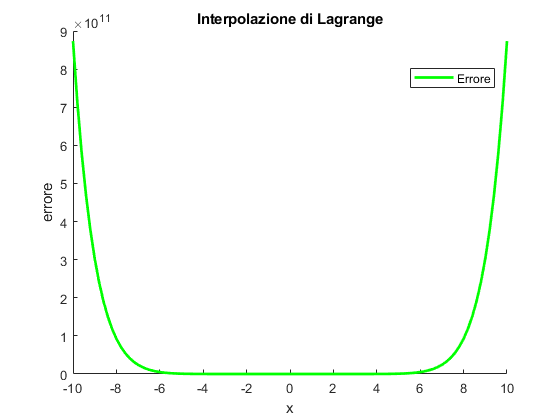


Errore Norma: 2104853271116.6685


errLagrange(x, yi, y1);

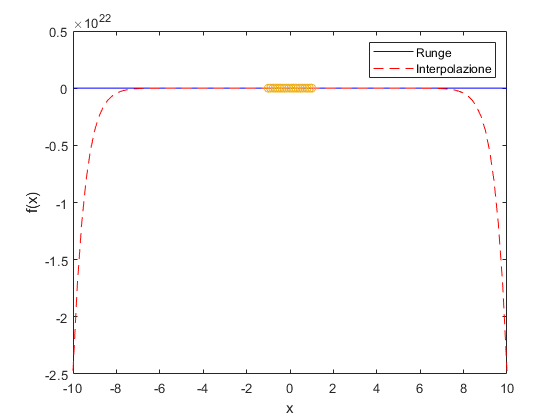

% Tabella di 20 punti 
table = funTable(y1, -1, 1, 20, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

     x              f(x)                     yi                     Errore       
    ____    ____________________    _____________________    ____________________

     -10     0.00039984006397441    -2.47296729888883e+22    2.47296729888883e+22
    -9.8     0.00041631973355537    -1.71639148483958e+22    1.71639148483958e+22
    -9.6    0.000433839479392625    -1.18226600316615e+22    1.18226600316615e+22
    -9.4    0.000452488687782805    -8.07930690362152e+21    8.07930690362152e+21
    -9.2    0.000472366556447803    -5.47574215824769e+21    5.47574215824769e+21
      -9    0.000493583415597236    -3.67927025280756e+21    3.67927025280756e+21
    -8.8    0.000516262261228704    -2.44996014067637e+21    2.44996014067637e+21
    -8.6    0.000540540540540541    -1.61603861259351e+21    1.61603861259351e+21
    -8.4     0.00056657223796034    -1.0554

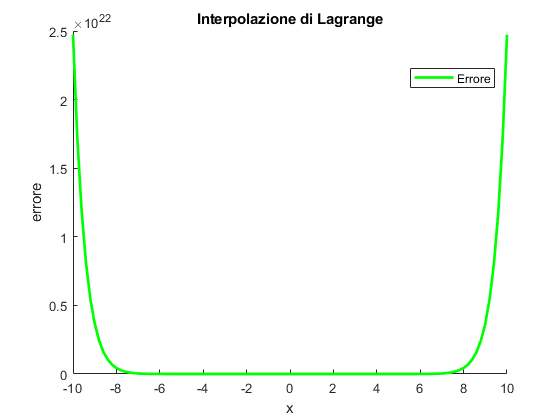


Errore Norma: 48274939561910946758656.0000


errLagrange(x, yi, y1);

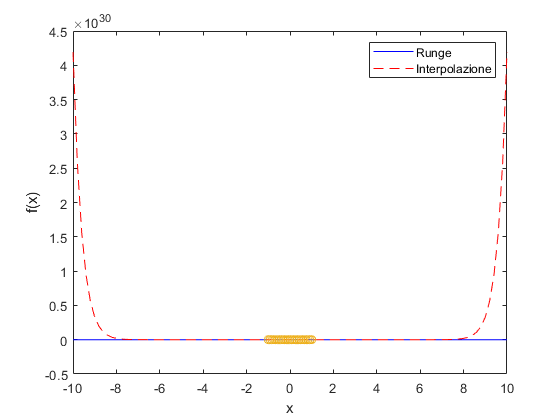

% Tabella di 25 punti 
table = funTable(y1, -1, 1, 25, 1);
yi = lagrange(x, table);
plot(x, y1(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('Runge', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

     x              f(x)                     yi                    Errore       
    ____    ____________________    ____________________    ____________________

     -10     0.00039984006397441    4.19306124227618e+30    4.19306124227618e+30
    -9.8     0.00041631973355537    2.57712900262398e+30    2.57712900262398e+30
    -9.6    0.000433839479392625    1.56800337671877e+30    1.56800337671877e+30
    -9.4    0.000452488687782805    9.44009495177735e+29    9.44009495177735e+29
    -9.2    0.000472366556447803    5.62114282468029e+29    5.62114282468029e+29
      -9    0.000493583415597236    3.30886249019294e+29    3.30886249019294e+29
    -8.8    0.000516262261228704    1.92446925484369e+29    1.92446925484369e+29
    -8.6    0.000540540540540541    1.10529371098275e+29    1.10529371098275e+29
    -8.4     0.00056657223796034    6.26495028920568e

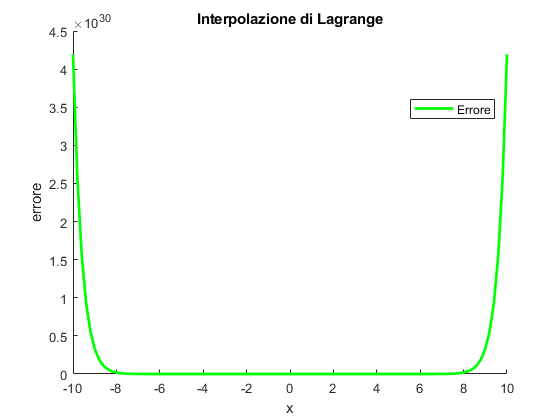


Errore Norma: 7490464898078290869738551640064.0000


errLagrange(x, yi, y1);

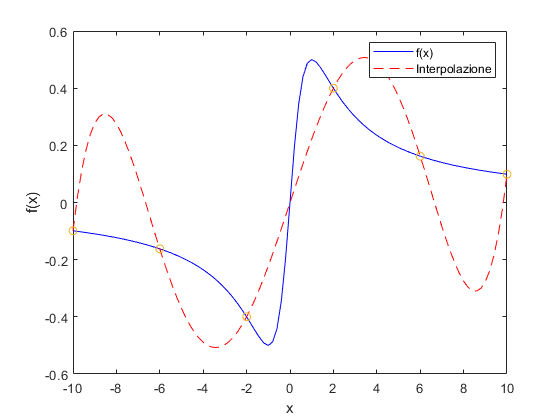

% Tabella di 5 punti 
table = funTable(y2, -10, 10, 6, 1);
yi = lagrange(x, table);
plot(x, y2(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('f(x)', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

     x             f(x)                    yi                     Errore       
    ____    __________________    _____________________    ____________________

     -10    -0.099009900990099       -0.099009900990099                       0
    -9.8    -0.100989282769992       0.0172861824993306       0.118275465269322
    -9.6    -0.103048518677544        0.111025220230131       0.214073738907675
    -9.4    -0.105192479856759        0.184262336633663       0.289454816490422
    -9.2    -0.107426436244745        0.238954010168584        0.34638044641333
      -9    -0.109756097560976        0.276960128445277       0.386716226006253
    -8.8    -0.112187659357471        0.300046043350281       0.412233702707752
    -8.6    -0.114727854855923        0.309884626170725       0.424612481026648
    -8.4    -0.117384013415316        0.308058322718758       0

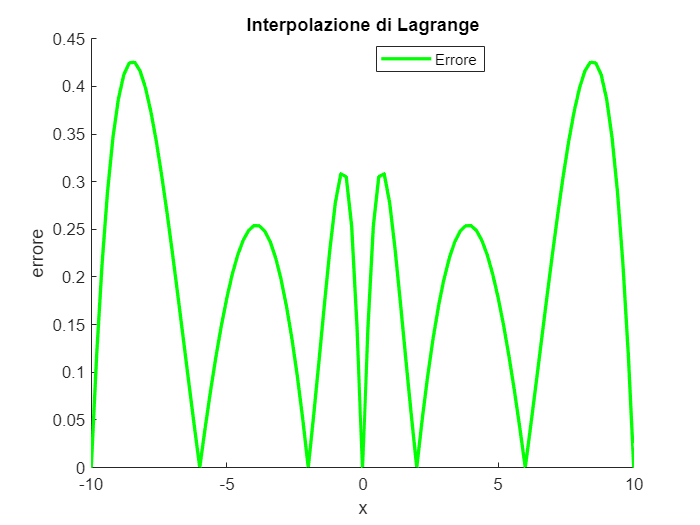


Errore Norma: 2.4223


errLagrange(x, yi, y2);

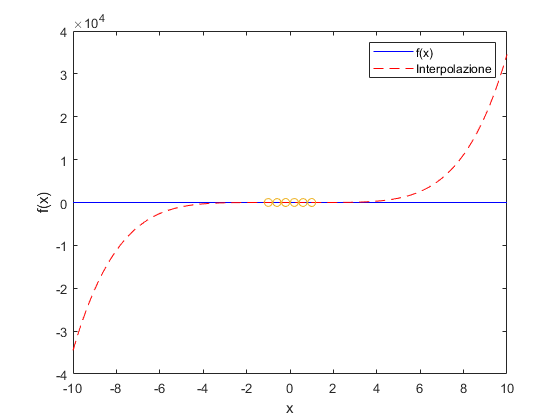

% Tabella di 6 punti 
table = funTable(y2, -1, 1, 6, 1);
yi = lagrange(x, table);
plot(x, y2(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('f(x)', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

     x             f(x)                    yi                     Errore       
    ____    __________________    _____________________    ____________________

     -10    -0.099009900990099        -34512.2115384615        34512.1125285606
    -9.8    -0.100989282769992        -31165.4411764706        31165.3401871878
    -9.6    -0.103048518677544        -28082.9049773756        28082.8019288569
    -9.4    -0.105192479856759        -25248.6764705882        25248.5712781083
    -9.2    -0.107426436244745        -22647.4807692307        22647.3733427945
      -9    -0.109756097560976        -20264.6809954751        20264.5712393776
    -8.8    -0.112187659357471        -18086.2647058823         18086.152518223
    -8.6    -0.114727854855923         -16098.830316742        16098.7155888872
    -8.4    -0.117384013415316        -14289.5735294117        

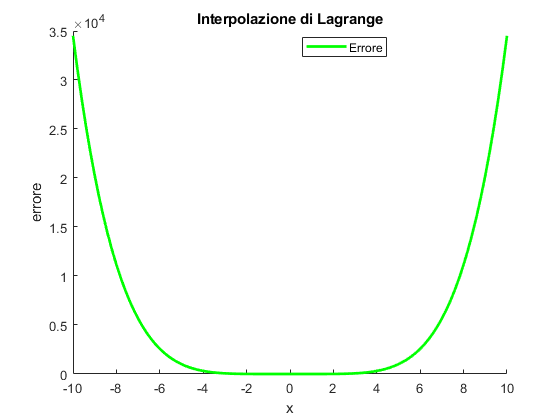


Errore Norma: 109293.9347


errLagrange(x, yi, y2);

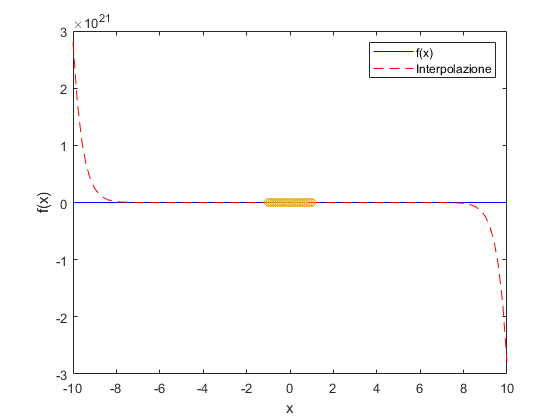

% Tabella di 25 punti 
table = funTable(y2, -1, 1, 25, 1);
yi = lagrange(x, table);
plot(x, y2(x), 'b-', x, yi, 'r--', table(:,1), table(:,2), 'o');
legend('f(x)', 'Interpolazione');
xlabel('x');
ylabel('f(x)');

     x             f(x)                    yi                     Errore       
    ____    __________________    _____________________    ____________________

     -10    -0.099009900990099     2.79853592531685e+21    2.79853592531685e+21
    -9.8    -0.100989282769992     1.75444844609573e+21    1.75444844609573e+21
    -9.6    -0.103048518677544     1.08921633764416e+21    1.08921633764416e+21
    -9.4    -0.105192479856759      6.6942781248206e+20     6.6942781248206e+20
    -9.2    -0.107426436244745     4.07081715307429e+20    4.07081715307429e+20
      -9    -0.109756097560976     2.44835062778484e+20    2.44835062778484e+20
    -8.8    -0.112187659357471     1.45554086356136e+20    1.45554086356136e+20
    -8.6    -0.114727854855923     8.54914930789403e+19    8.54914930789403e+19
    -8.4    -0.117384013415316     4.95808130595244e+19    4.95

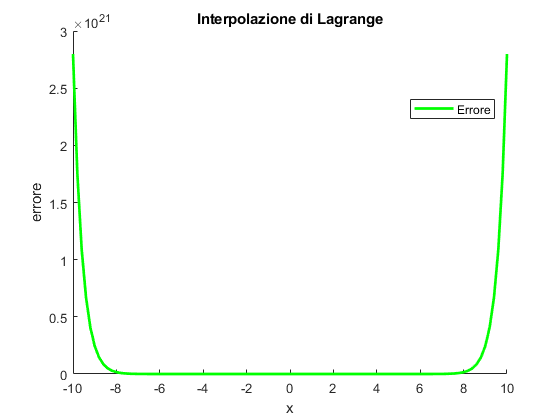


Errore Norma: 5060075048339183239168.0000


errLagrange(x, yi, y2);